export_images = true;

u = linspace(0, 1, 21);

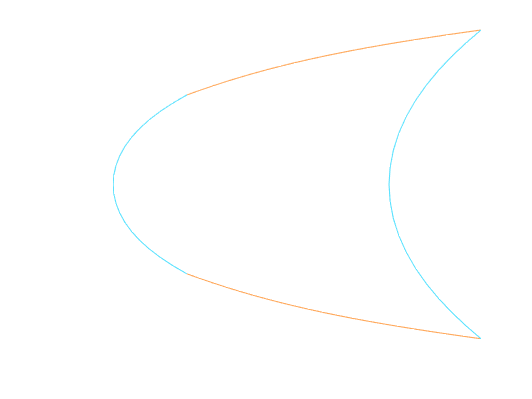

Bx = [4 7 10 14; 2 0 0 12; 1 0 0 10; 1 0 0 10; 2 0 0 12; 4 7 10 14];
By = [5 3 2 1; 7 0 0 4; 9 0 0 8; 12 0 0 13; 14 0 0 17; 16 18 19 20];

c1 = [Bx(1, :); By(1, :)]';
c2 = [Bx(end, :); By(end, :)]';
c3 = [Bx(:, 1) By(:, 1)];
c4 = [Bx(:, end) By(:, end)];

b1 = bezier(c1, u);
b2 = bezier(c2, u);
b3 = bezier(c3, u);
b4 = bezier(c4, u);

figure
plot(b1(:, 1), b1(:, 2), Color='#FFAA5E');
hold on
plot(b2(:, 1), b2(:, 2), Color='#FFAA5E');
hold on 
plot(b3(:, 1), b3(:, 2), Color='#5EE3FF');
hold on 
plot(b4(:, 1), b4(:, 2), Color='#5EE3FF');

grid off
set(gca, 'visible', 'off')
view([-0.50 90.00])

if export_images
    exportgraphics(gcf, 'border1.pdf', 'ContentType', 'vector')
end

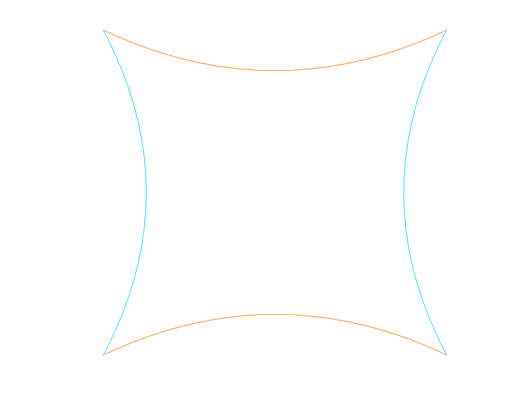

Bx = [1 3 6 9 11; 2 0 0 0 10; 3 0 0 0 9; 2 0 0 0 10; 1 3 6 9 11];
By = [1 2 3 2 1; 3 0 0 0 3; 6 0 0 0 6; 9 0 0 0 9; 11 10 9 10 11];

c1 = [Bx(1, :); By(1, :)]';
c2 = [Bx(end, :); By(end, :)]';
c3 = [Bx(:, 1) By(:, 1)];
c4 = [Bx(:, end) By(:, end)];

b1 = bezier(c1, u);
b2 = bezier(c2, u);
b3 = bezier(c3, u);
b4 = bezier(c4, u);

figure
plot(b1(:, 1), b1(:, 2), Color='#FFAA5E');
hold on
plot(b2(:, 1), b2(:, 2), Color='#FFAA5E');
hold on 
plot(b3(:, 1), b3(:, 2), Color='#5EE3FF');
hold on 
plot(b4(:, 1), b4(:, 2), Color='#5EE3FF');

grid off
set(gca, 'visible', 'off')
view([-0.50 90.00])

if export_images
    exportgraphics(gcf, 'border2.pdf', 'ContentType', 'vector')
end

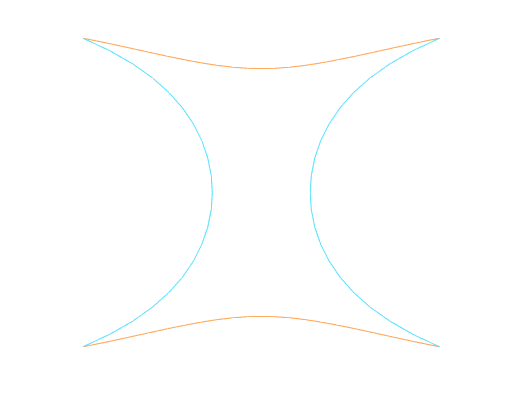

Bx = [1 10 14 18 27; 8 0 0 0 20; 11 0 0 0 17; 12 0 0 0 16; 11 0 0 0 17; 8 0 0 0 20; 1 10 14 18 27];
By = [1 4 7 4 1; 6 0 0 0 6; 12 0 0 0 12; 20 0 0 0 20; 28 0 0 0 28; 34 0 0 0 34; 39 36 33 36 39];

c1 = [Bx(1, :); By(1, :)]';
c2 = [Bx(end, :); By(end, :)]';
c3 = [Bx(:, 1) By(:, 1)];
c4 = [Bx(:, end) By(:, end)];

b1 = bezier(c1, u);
b2 = bezier(c2, u);
b3 = bezier(c3, u);
b4 = bezier(c4, u);

figure
plot(b1(:, 1), b1(:, 2), Color='#FFAA5E');
hold on
plot(b2(:, 1), b2(:, 2), Color='#FFAA5E');
hold on 
plot(b3(:, 1), b3(:, 2), Color='#5EE3FF');
hold on 
plot(b4(:, 1), b4(:, 2), Color='#5EE3FF');

grid off
set(gca, 'visible', 'off')
view([-0.50 90.00])

if export_images
    exportgraphics(gcf, 'border3.pdf', 'ContentType', 'vector')
end

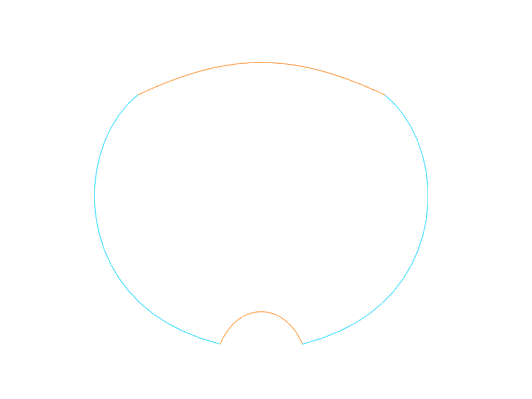

Bx = [1 2 4 6 7; -5 0 0 0 13; -8 0 0 0 16; -10 0 0 0 18; -8 0 0 0 16; -5 0 4 8 13];
By = [1 4 5 4 1; 3 0 0 0 3; 7 0 0 0 7; 14 0 0 0 14; 21 0 0 0 21; 24 27 28 27 24];

c1 = [Bx(1, :); By(1, :)]';
c2 = [Bx(end, :); By(end, :)]';
c3 = [Bx(:, 1) By(:, 1)];
c4 = [Bx(:, end) By(:, end)];

b1 = bezier(c1, u);
b2 = bezier(c2, u);
b3 = bezier(c3, u);
b4 = bezier(c4, u);

figure
plot(b1(:, 1), b1(:, 2), Color='#FFAA5E');
hold on
plot(b2(:, 1), b2(:, 2), Color='#FFAA5E');
hold on 
plot(b3(:, 1), b3(:, 2), Color='#5EE3FF');
hold on 
plot(b4(:, 1), b4(:, 2), Color='#5EE3FF');

grid off
set(gca, 'visible', 'off')
view([-0.50 90.00])

if export_images
    exportgraphics(gcf, 'border4.pdf', 'ContentType', 'vector')
end

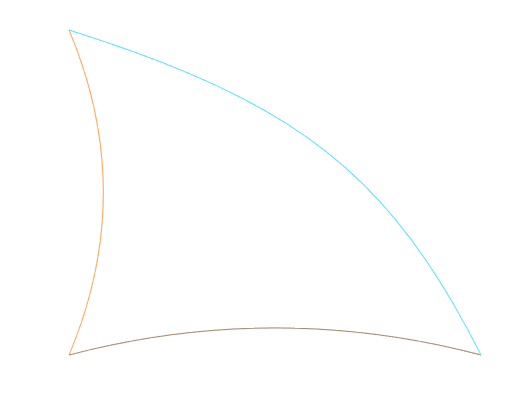

Bx = [1 4 7 10; 2 0 8 NaN; 2 6 NaN NaN; 1 NaN NaN NaN];
By = [1 2 2 1; 4 0 6 NaN; 7 8 NaN NaN; 10 NaN NaN NaN];

b1 = [Bx(:, 1) By(:, 1)];
b2 = [Bx(1, :); By(1, :)]';

b3 = [];
n = size(Bx, 1);

for i = 1:n
    b3 = [b3; Bx(i, n-i+1) By(i, n-i+1)];
end

c1 = bezier(b1, u);
c2 = bezier(b2, u);
c3 = bezier(b3, u);

figure
plot(c1(:, 1), c1(:, 2), Color='#FFAA5E');
hold on
plot(c2(:, 1), c2(:, 2), Color='#AA8F78');
hold on
plot(c3(:, 1), c3(:, 2), Color='#5EE3FF');

grid off
set(gca, 'visible', 'off')
view([-0.50 90.00])

if export_images
    exportgraphics(gcf, '3border1.pdf', 'ContentType', 'vector')
end

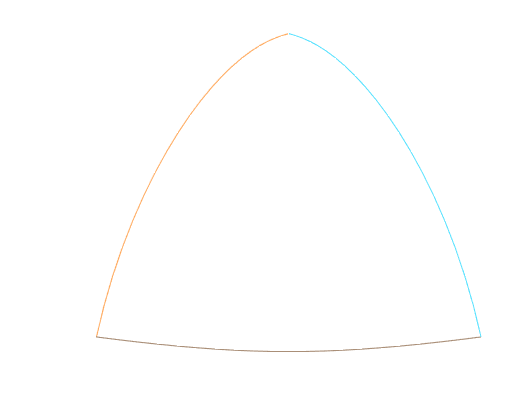

Bx = [1 4 7 9 12 15; 2 0 0 0 14 NaN; 4 0 0 12 NaN NaN; 6 0 10 NaN NaN NaN; 7 9 NaN NaN NaN NaN; 8 NaN NaN NaN NaN NaN];
By = [1.5 1.2 1 1 1.2 1.5; 5 0 0 0 5 NaN; 8 0 0 8 NaN NaN; 9.3 0 9.3 NaN NaN NaN; 9.7 9.7 NaN NaN NaN NaN; 9.9 NaN NaN NaN NaN NaN];

b1 = [Bx(:, 1) By(:, 1)];
b2 = [Bx(1, :); By(1, :)]';

b3 = [];
n = size(Bx, 1);

for i = 1:n
    b3 = [b3; Bx(i, n-i+1) By(i, n-i+1)];
end

c1 = bezier(b1, u);
c2 = bezier(b2, u);
c3 = bezier(b3, u);

figure
plot(c1(:, 1), c1(:, 2), Color='#FFAA5E');
hold on
plot(c2(:, 1), c2(:, 2), Color='#AA8F78');
hold on
plot(c3(:, 1), c3(:, 2), Color='#5EE3FF');

grid off
set(gca, 'visible', 'off')
view([-0.50 90.00])

if export_images
    exportgraphics(gcf, '3border2.pdf', 'ContentType', 'vector')
end

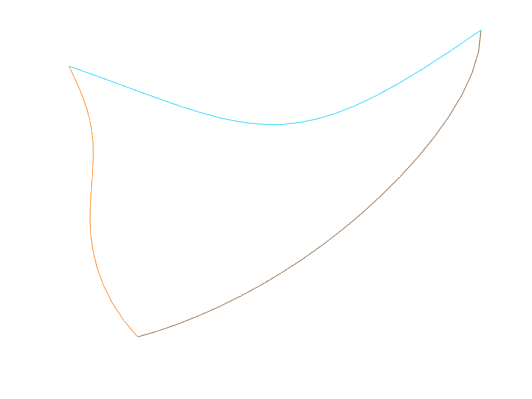

Bx = [2 4 6 8 10 12 12; 0.5 0 0 0 0 9 NaN; 0 0 0 0 7 NaN NaN; 1 0 0 6 NaN NaN NaN; 1 0 4 NaN  NaN NaN NaN; 0.5 3 NaN NaN NaN NaN NaN; 0 NaN NaN NaN NaN NaN NaN];
By = [-0.5 0 1 2 4 6 8; 1 0 0 0 0 6 NaN; 3 0 0 0 5 NaN NaN; 4 0 0 5 NaN NaN NaN; 5 0 5.5 NaN  NaN NaN NaN; 6 6 NaN NaN NaN NaN NaN; 7 NaN NaN NaN NaN NaN NaN];

b1 = [Bx(:, 1) By(:, 1)];
b2 = [Bx(1, :); By(1, :)]';

b3 = [];
n = size(Bx, 1);

for i = 1:n
    b3 = [b3; Bx(i, n-i+1) By(i, n-i+1)];
end

c1 = bezier(b1, u);
c2 = bezier(b2, u);
c3 = bezier(b3, u);

figure
plot(c1(:, 1), c1(:, 2), Color='#FFAA5E');
hold on
plot(c2(:, 1), c2(:, 2), Color='#AA8F78');
hold on
plot(c3(:, 1), c3(:, 2), Color='#5EE3FF');

grid off
set(gca, 'visible', 'off')
view([-0.50 90.00])

if export_images
    exportgraphics(gcf, '3border3.pdf', 'ContentType', 'vector')
end